M = 0.5;
m = 0.5;
b = 0;
I = 0.006;
g = -9.80665;
l = 0.3;
q = (M+m)*(I+m*l^2)-(m*l)^2;
s = tf('s');

P_cart = (((I+m*l^2)/q)*s^2 - (m*g*l/q))/(s^4 + (b*(I + m*l^2))*s^3/q - ((M + m)*m*g*l)*s^2/q - b*m*g*l*s/q)


P_cart =
 
    0.051 s^2 + 1.471
  ----------------------
  0.0285 s^4 + 1.471 s^2
 
Continuous-time transfer function.





P_pend = (m*l*s/q)/(s^3 + (b*(I + m*l^2))*s^2/q - ((M + m)*m*g*l)*s/q - b*m*g*l/q)


P_pend =
 
         0.004275 s
  -------------------------
  0.0008122 s^3 + 0.04192 s
 
Continuous-time transfer function.



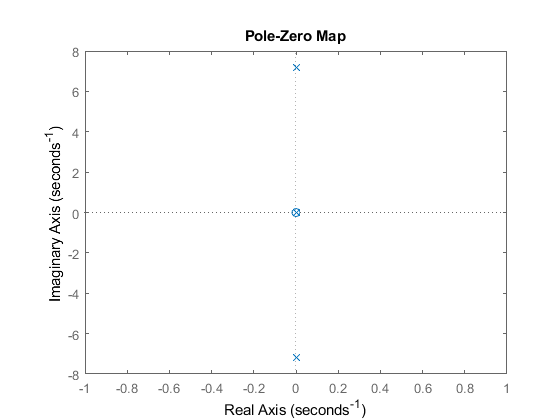

pzplot    (P_pend)

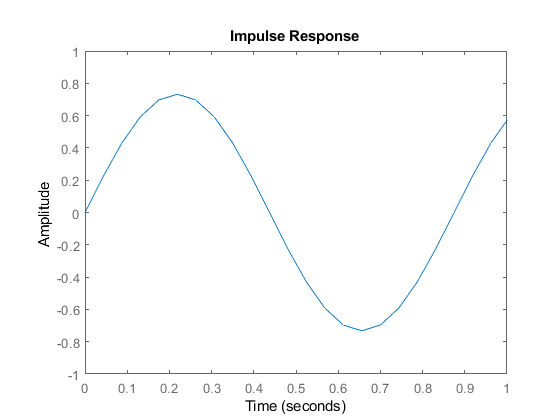


h = impulseplot(P_pend); % Use this command to return plot handle to programmatically customize the plot. 
p = getoptions(h);
p.XLim = {[0, 1]};
p.YLim = {[-1, 1]};
setoptions(h,p);

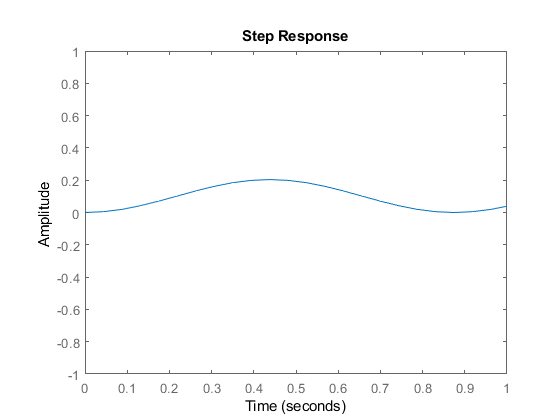


h = stepplot(P_pend); % Use this command to return plot handle to programmatically customize the plot. 
p = getoptions(h);
p.XLim = {[0, 1]};
p.YLim = {[-1, 1]};
setoptions(h,p);

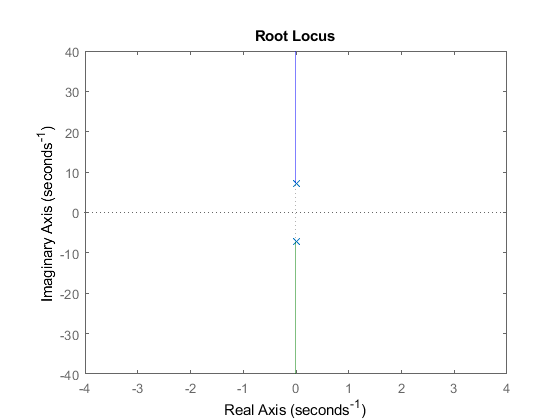


rlocus    (P_pend)

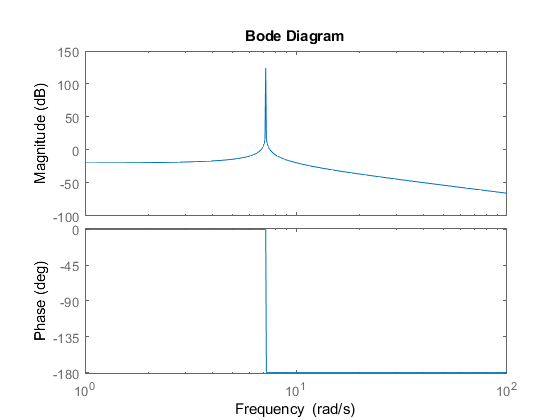


bode      (P_pend)

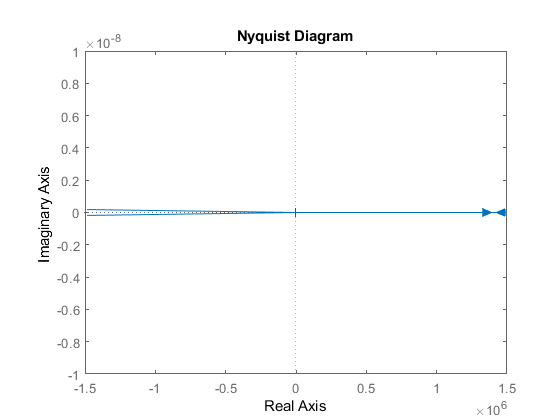


nyquist   (P_pend)